clc; clear all; close all;

s= tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


%plantas reales
G1 = (3*s -2)/(s^2+2*s+1)

G1 =
 
     3 s - 2
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


G2 = 1/(s-1)

G2 =
 
    1
  -----
  s - 1
 
Continuous-time transfer function.
Model Properties



%plantas estimadas
G1es = (3.1*s-2.1)/(s^2+2.1*s+1.01)

G1es =
 
     3.1 s - 2.1
  ------------------
  s^2 + 2.1 s + 1.01
 
Continuous-time transfer function.
Model Properties


G2es = 1.3/(s-1.2)

G2es =
 
    1.3
  -------
  s - 1.2
 
Continuous-time transfer function.
Model Properties



%para G1 
INV = (3.1*s+2.1)\(s^2+2.1*s+1.01)

INV =
 
  s^2 + 2.1 s + 1.01
  ------------------
     3.1 s + 2.1
 
Continuous-time transfer function.
Model Properties


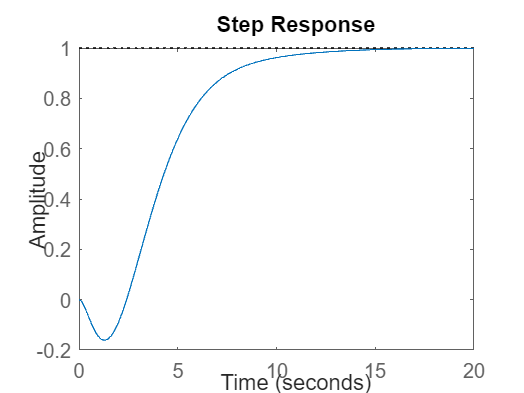

INV = INV/(dcgain(INV)*dcgain(G1es));
Lambda2 = 1;
gamma2 = 0.01;
F = (gamma2*s+1)/(Lambda2*s+1)^2; % n >= 1 + deg(INV) = 1+1 =2
q = INV*F;
C = q/(1-q*G1es);
IMC_CL = feedback(C*G1,1);
step(IMC_CL);


G12 = G2es*IMC_CL

G12 =
 
               -0.1209 s^9 - 12.84 s^8 - 76.96 s^7 - 189 s^6 - 226.8 s^5 - 108.6 s^4 + 39.02 s^3 + 74.19 s^2 + 34.22 s + 5.57
  ----------------------------------------------------------------------------------------------------------------------------------------
  9.61 s^11 + 79.33 s^10 + 276.1 s^9 + 500.1 s^8 + 414.3 s^7 - 137.3 s^6 - 752.1 s^5 - 906.4 s^4 - 604.5 s^3 - 240.9 s^2 - 53.72 s - 5.141
 
Continuous-time transfer function.


Gss = ss(G12)

Gss =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10     x11
   x1   -8.255  -7.183  -3.252  -1.347  0.4464   1.223   1.474  0.9828  0.7835  0.3494  0.1337
   x2        4       0       0       0       0       0       0       0       0       0       0
   x3        0       4       0       0       0       0       0       0       0       0       0
   x4        0       0       2       0       0       0       0       0       0       0       0
   x5        0       0       0       1       0       0       0       0       0       0       0
   x6        0       0       0       0       2       0       0       0       0       0       0
   x7        0       0       0       0       0       1       0       0       0       0       0
   x8        0       0       0       0       0       0       1       0       0       0       0
   x9        0       0       0       0       0       0       0     0.5       0       0       0
   x10       0       0       0     

A = Gss.A;
B = Gss.B;
C = Gss.C

C =          0   -0.0016   -0.0418   -0.1251   -0.3073   -0.1844   -0.0883    0.0317    0.1206    0.1113    0.0724


D = Gss.D

D = 0



nx = size(A,1)

nx = 11

ny = size(C,1)

ny = 1

nu = size(B,2)

nu = 1


%%Aumentar
AOL=[A zeros(nx,ny);-C zeros(ny,ny)]

AOL =    -8.2552   -7.1825   -3.2523   -1.3472    0.4464    1.2229    1.4737    0.9828    0.7835    0.3494    0.1337         0
    4.0000         0         0         0         0         0         0         0         0         0         0         0
         0    4.0000         0         0         0         0         0         0         0         0         0         0
         0         0    2.0000         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    2.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0      

BOL=[B;zeros(ny,nu)]

BOL =      2
     0
     0
     0
     0
     0
     0
     0
     0
     0


QOL=diag([1 1 1 1 1 1 1 1 1 1 1 100])

QOL =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0


ROL=0.001;
KOL=lqr(AOL,BOL,QOL,ROL)

KOL =    34.2123  113.2278  171.3077  308.4897  730.1690  590.4669  652.5204  482.0721  453.2544  245.0485  115.6090 -316.2278


K=KOL(:,1:nx)

K =    34.2123  113.2278  171.3077  308.4897  730.1690  590.4669  652.5204  482.0721  453.2544  245.0485  115.6090


Ki=-KOL(:,(nx+1):end)

Ki = 316.2278


%2do paso LQG
Gw=eye(nx);
Qw=0.1*eye(nx);
Vv=0.0001*eye(ny);
L=lqe(A,Gw,C,Qw,Vv)

L =     7.7277
   -6.1027
  -60.3603
  -87.1029
  -41.1773
  -32.5398
  -48.9935
  -88.3699
  -73.8378
  -56.2966


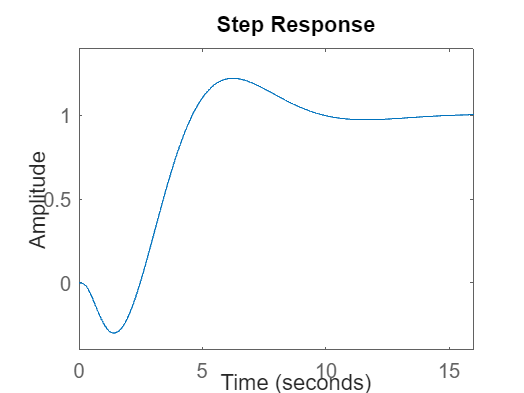


%REMPLAZO POR LA PLANTA REAL
A = ss(G2*IMC_CL).A;
B = ss(G2*IMC_CL).B;
C = ss(G2*IMC_CL).C;
D = ss(G2*IMC_CL).D;

%Cerramos el Lazo
ACL=[A -B*K B*Ki;L*C A-B*K-L*C B*Ki;-C D*K -D*Ki];
BCL=[zeros(nx,ny);zeros(nx,ny);eye(ny,ny)];
CCL=[C -D*K D*Ki];
DCL=[zeros(ny,ny)];
GCL=ss(ACL,BCL,CCL,DCL);
step(GCL)